# **Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the panda_tray rigid body tree (RBT) model.

robot = importrobot('panda_tray/panda_tray.urdf');

robot.DataFormat = 'column';
showdetails(robot); % To find out the end effector name

--------------------
Robot: (11 bodies)

 Idx                Body Name                Joint Name                Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                ----------                ----------                ----------------   ----------------
   1              panda_link1              panda_joint1                  revolute                  panda_link0(0)   panda_link2(2)  
   2              panda_link2              panda_joint2                  revolute                  panda_link1(1)   panda_link3(3)  
   3              panda_link3              panda_joint3                  revolute                  panda_link2(2)   panda_link4(4)  
   4              panda_link4              panda_joint4                  revolute                  panda_link3(3)   panda_link5(5)  
   5              panda_link5              panda_joint5                  revolute                  panda_link4(4)   panda_link6(6)  
   6              panda_link

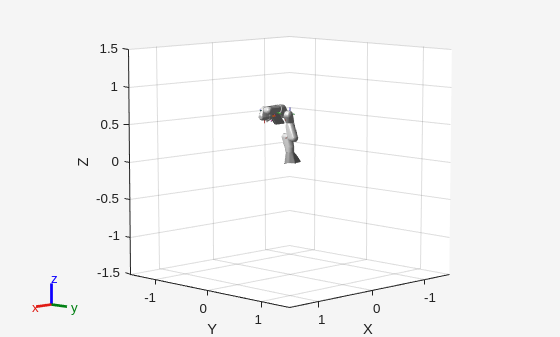

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "tray_base"; 

Specify initial and desired end-effector poses. Use inverse kinematics (maps from pose to joint angles) to solve for the initial robot configuration given a desired pose.

% your known joint values (row)
q_start = [0.1, -1.24, 0.29, -2.3, 0.12, 2.68, -0.63];

% make sure it's a column vector (robot.DataFormat = 'column')
q_start = q_start(:);    % now numJoints x 1

% sanity check
numJoints = numel(homeConfiguration(robot));   % or set manually
if numel(q_start) ~= numJoints
    error('q_desired must contain %d joint values', numJoints);
end

% wrap angles into [-pi,pi] if you want
q_start = wrapToPi(q_start);

% set current robot joint configuration (numeric column)
currentRobotJConfig = q_start;

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.151, 0.614, 0.958]) * eul2tform([0, 0, -1.918], 'XYZ');  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

q_final = [0.63, 0.17, 0.84, -1.01, -0.55, 2.68, -0.43];

% make sure it's a column vector (robot.DataFormat = 'column')
q_final = q_final(:);    % now numJoints x 1

% sanity check
numJoints = numel(homeConfiguration(robot));   % or set manually
if numel(q_final) ~= numJoints
    error('q_desired must contain %d joint values', numJoints);
end

% wrap angles into [-pi,pi] if you want
q_final = wrapToPi(q_final);

% set current robot joint configuration (numeric column)
finalRobotJConfig = q_final;

## Collision Cylinder

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstacle;
% After running helperCreateObstaclesIIWA.m
fprintf('occupied voxels (nnz) = %d\n', nnz(voxel_world.voxel));

occupied voxels (nnz) = 2197


fprintf('voxel grid size = [%d %d %d]\n', size(voxel_world.voxel));

voxel grid size = [100 100 100]


fprintf('number of collision objects in world = %d\n', numel(world));

number of collision objects in world = 1


Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

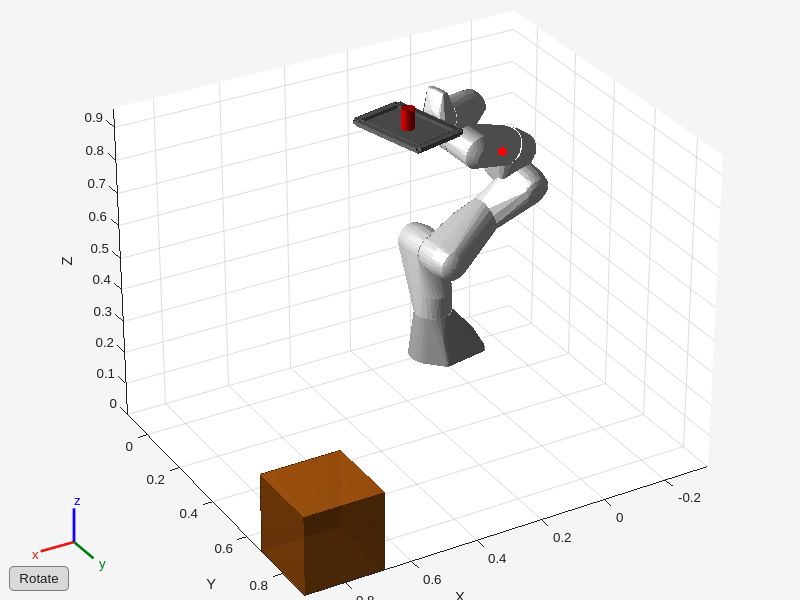

q_desired = [0.1, -1.24, 0.29, -2.3, 0.12, 2.68, -0.63];
q_desired = reshape(q_desired, 1, []);                
if numel(q_desired) ~= numJoints
    error('q_desired must contain %d joint values', numJoints);
end
x0 = [q_desired, zeros(1, numJoints)];
helperInitialVisualizer;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 2.755898 seconds.


Qtheta = 8.1274

RAR = 5.8433

Elapsed time is 2.739116 seconds.


Qtheta = 7.8925

RAR = 5.8441

Elapsed time is 2.664005 seconds.


Qtheta = 8.2837

RAR = 5.8442

Elapsed time is 2.699994 seconds.


Qtheta = 8.1813

RAR = 5.8443

Elapsed time is 2.708790 seconds.


Qtheta = 8.2581

RAR = 5.8413

STOMP Finished.


isTrajectoryInCollision = logical
   0


robot_name = "panda_tray"

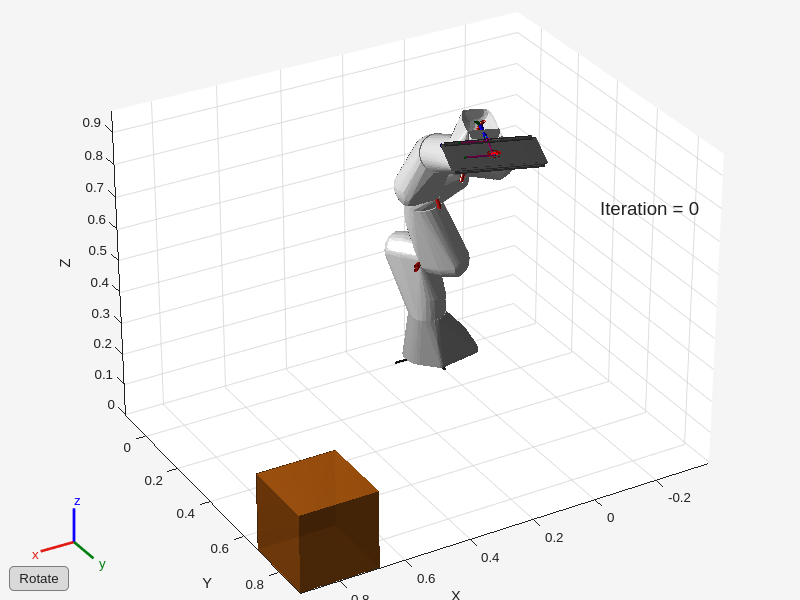

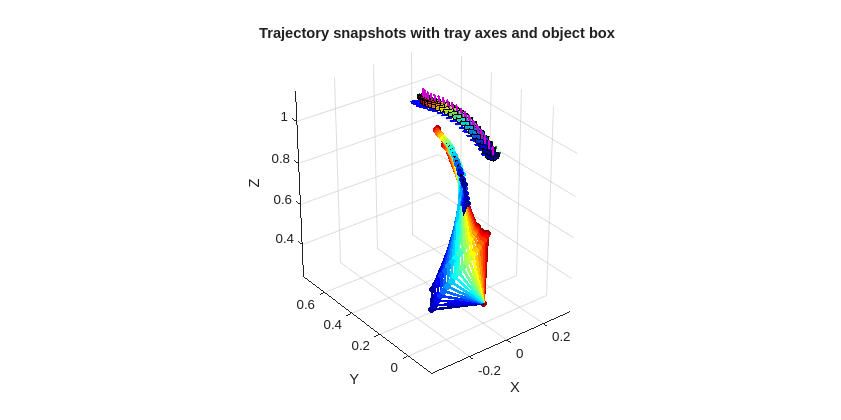

helperSTOMP;

% Add jerk constraint

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.